### Setup

clear variables
ProgramStart = tic;
% Sound driver parameters
Buffersize = 1024;
RecorderChannelMapping = [1 2 3 4 5 6];

% Struct for often used constants
Constants = struct( ...
    'Samplerate', 48000, ...
    'AmountOfMicrophones', length(RecorderChannelMapping), ...
    'UCARadius', 0.40 / 2, ...
    'SpeedOfSound', 343, ...
    'SoundOutputOffset', 0.116 / 2, ... % From Genelec 8010A datasheet (half depth)
    'AlphaOffset', 30, ... % Offset betweeen x-axis and mic 1 in degrees
    'AmountOfTaus', 301, ...
    'AmountOfPhis', 360, ...
    'AmountOfOmegas', 601 ...
    );

% Distance parameters
MinDistance = 0.5;
MaxDistance = 2.0;

% Execution paths
Synthesized = true;

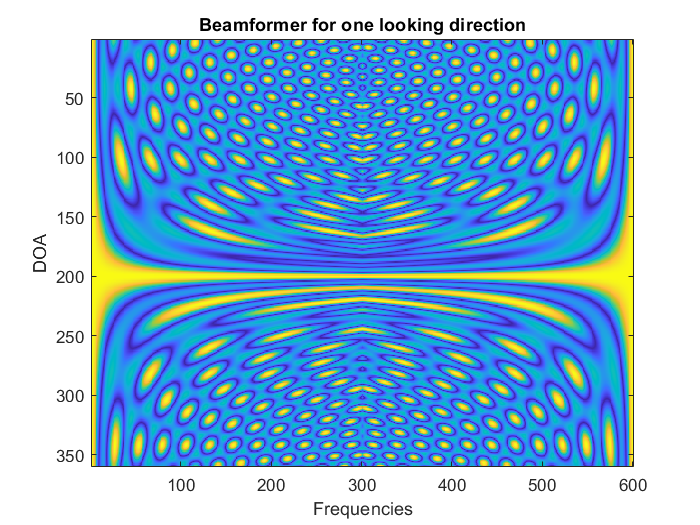

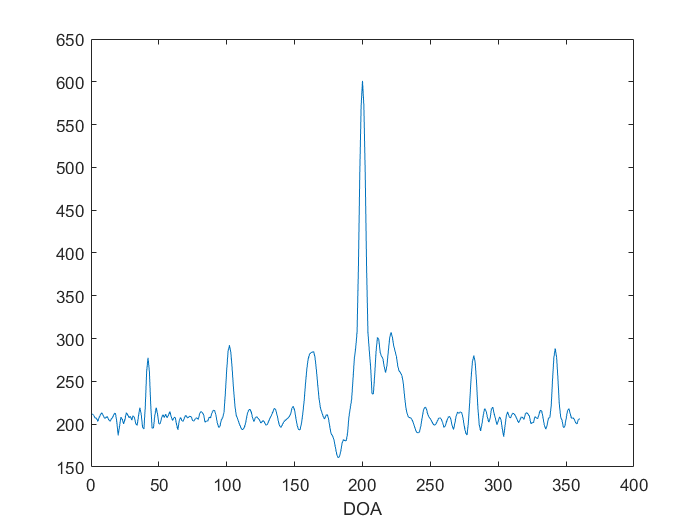

PrecalcStart = tic;
if Synthesized
    load("synthesized_signals.mat")
    ProbeSound = signals.clean;
    Constants.SignalLength = length(ProbeSound);
    Constants.AmountOfMicrophones = 6;
    Constants.AlphaOffset = 30;
    Constants.Samplerate = 24000;
else
    t = 0:1/Constants.Samplerate:0.5;
    ProbeSound = transpose(chirp(t, 50, t(end), 1000, "linear"));
end

% Beamformer
Constants.Betas = UCAangles(Constants.AmountOfMicrophones, Constants.AlphaOffset); % In radians

Omegas = linspace(0, Constants.Samplerate, Constants.AmountOfOmegas); % In Hz
OmegasAngular = Omegas * 2 * pi;
OmegasAngular(ceil(Constants.AmountOfOmegas/2+1):end) = OmegasAngular(ceil(Constants.AmountOfOmegas/2+1):end) - Constants.Samplerate * 2 * pi;

Phis = linspace(0, deg2rad(359), Constants.AmountOfPhis); % In radians

SteeringVectors = SteeringVector(Phis, OmegasAngular, Constants);
[~, wDSHermitian] = BeamformerDS(SteeringVectors, Constants, ...
    "Plot", true, "LookingDirection", 200);

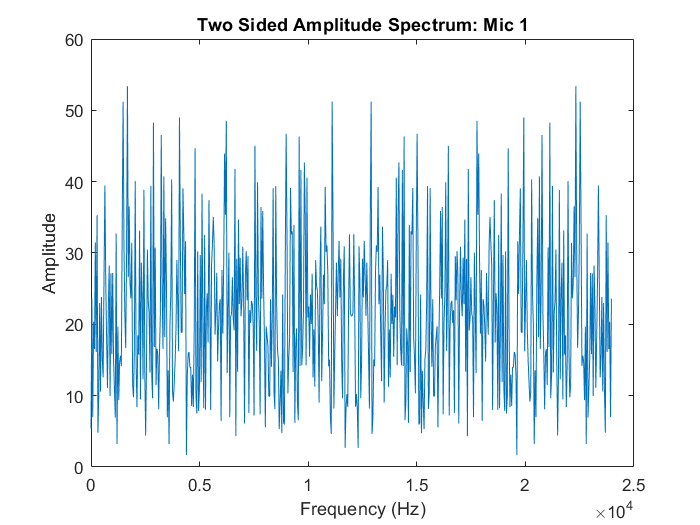


% Zbar
Taus = linspace(MinDistance, MaxDistance, Constants.AmountOfTaus); % In meters
TausSample = Taus * 2 / Constants.SpeedOfSound * Constants.Samplerate; % In samples

ProbeFFT = FFT(ProbeSound, ...
    "Plot", true, ...
    "Samplerate", Constants.Samplerate, ...
    "nFFT", Constants.AmountOfOmegas);


Zbar = CalculateZbar(ProbeFFT, TausSample, Constants);

toc(PrecalcStart);

Elapsed time is 1.307961 seconds.


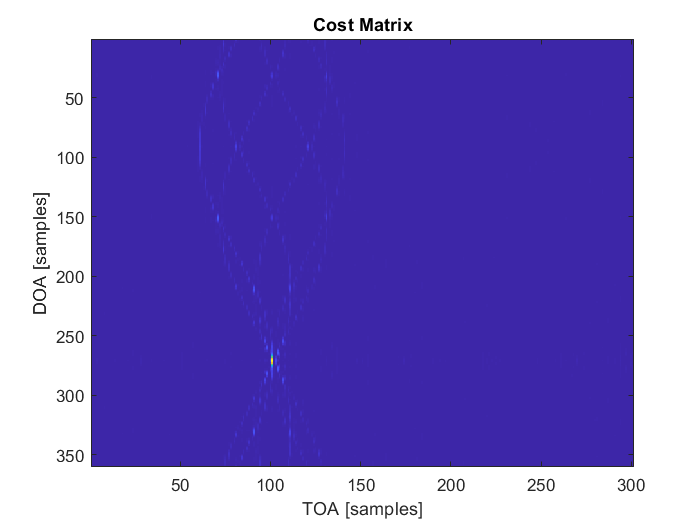

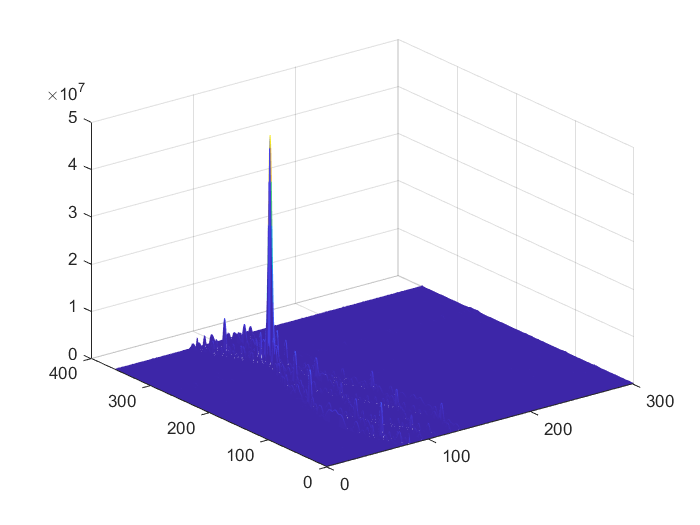

EchoStart = tic;
if Synthesized
    ReceivedSound = signals.observRefl;
else
    DirectSound = struct2array(load('Recordings\direct_term_3000_1amp.mat'));
    DirectSound(3040:end, :) = DirectSound(3040:end, :) * 0;
    ReceivedSound = struct2array(load('Recordings\0.7Meter30Degree_1amp_WGN.mat'));
    
    % DirectSound = RemoveDelay(DirectSound, Constants);
    % ReceivedSound = RemoveDelay(ReceivedSound, Constants);
    ReceivedSound = ReceivedSound - DirectSound;
end

ReceivedFFT = FFT(ReceivedSound, "nFFT", Constants.AmountOfOmegas);

Ybar = CalculateYbar(ReceivedFFT, wDSHermitian, Constants, ...
    "Plot", false);

CostMatrix = CostFunction(Ybar, Zbar, Constants, ...
    "Plot", true);
exportgraphics(gcf, 'testing_and_results\Echolocation_CostMatrix.pdf', "ContentType", "vector")

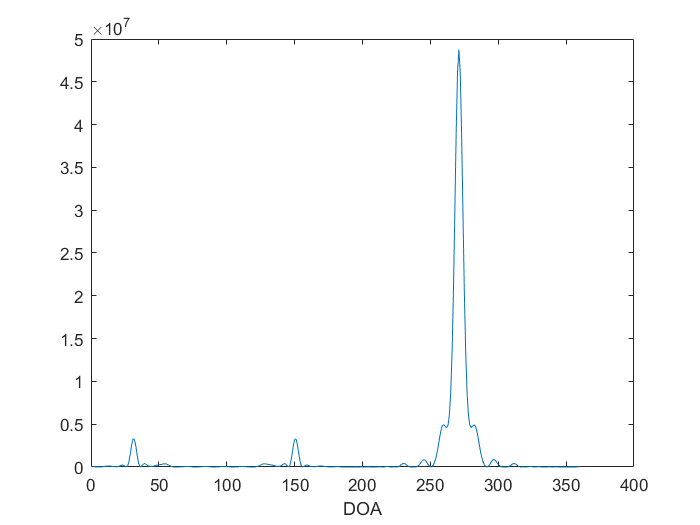

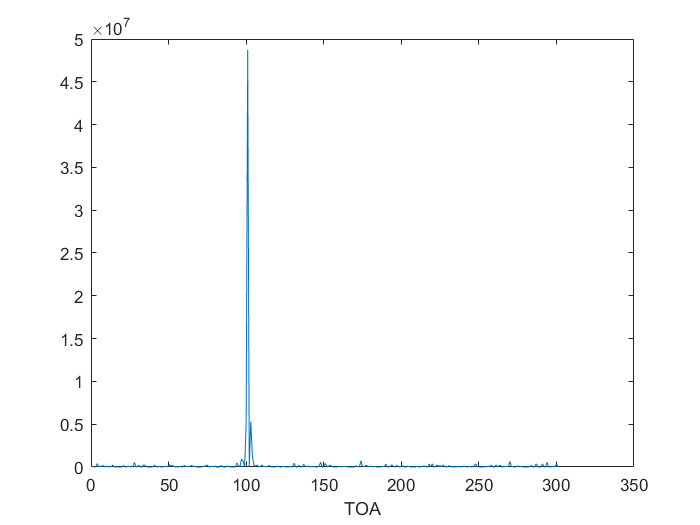



[Angle, Distance] = Estimator(Phis, TausSample, CostMatrix, Constants, ...
    "Plot", true);



toc(EchoStart)

Elapsed time is 2.452650 seconds.


toc(ProgramStart)

Elapsed time is 4.830188 seconds.
